%audio info

info = audiodevinfo

info = struct with fields:
     input: [1×5 struct]
    output: [1×4 struct]


nDevices = audiodevinfo(1)

nDevices = 5

% name = audiodevinfo(1,-1)
DriverVersion = audiodevinfo(1,0,"DriverVersion")

DriverVersion = 'Core Audio'

support = audiodevinfo(1,2,44100,16,1)

support = logical
   0


%devID = audiodevinfo(1,"devName")
suppDevID = audiodevinfo(1,44100,16,1)

suppDevID = 0

%record audio and plot
Fs = 44100; 
nBits = 8; 
nChannels = 1; 
ID = -1;       % default audio input device 
recObj = audiorecorder(Fs,nBits,nChannels,ID);

disp("Begin speaking.") 

Begin speaking.



recDuration = 3; % record for 3 seconds
recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.


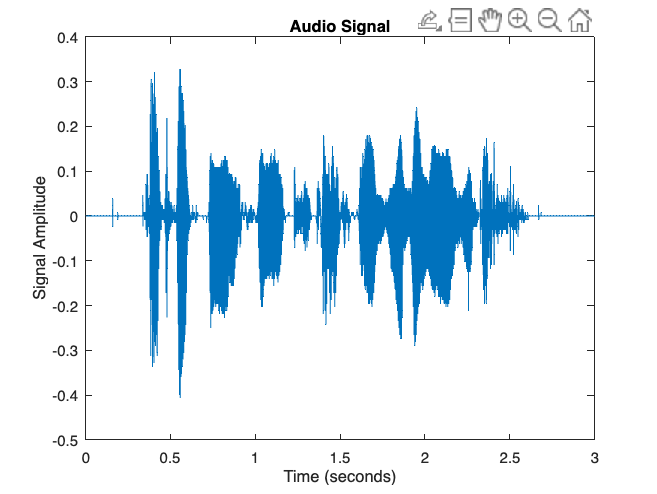


%play(recObj);

% disp(myRecording)
y = getaudiodata(recObj);
% xlim([0 5]);
plot(0:1/Fs:recDuration-1/Fs, y);
title('Audio Signal');
xlabel('Time (seconds)');

ylabel('Signal Amplitude');

%create  .wav file

filename = './ece2312_dog.wav';
% y_new = [zeros(25,1);y(1:end-25)]; %%%for one of the last parts
audiowrite(filename,y,Fs);
sound(y,Fs);

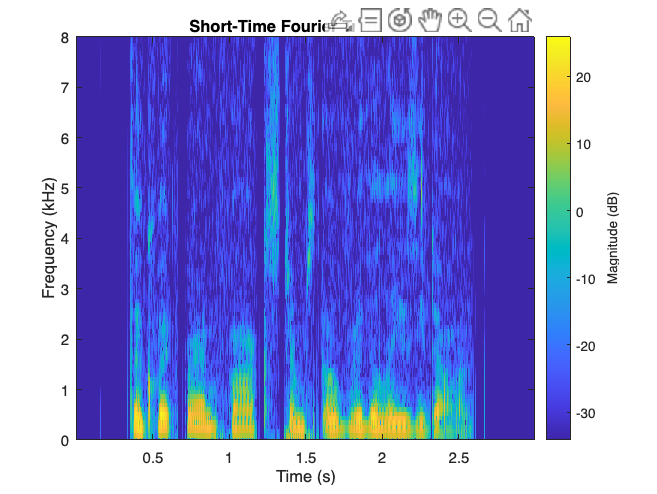

%plot .wav file

stft(y,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 8]) %can play around with limits to highlight speech section

%samples between ears
Fs = 44100;
sound_speed = 343; %343 meters/second
dist_Brooke = 10.5*10^-2; %10.5cm
dist_Abbie = 12.5*10^-2; %12.5cm
dist_Maria = 15*10^-2; %15cm

samples_Brooke = (dist_Brooke/sound_speed)*Fs;
samples_Abbie = (dist_Abbie/sound_speed)*Fs;
samples_Maria = (dist_Maria/sound_speed)*Fs;
avg_samples = (samples_Brooke + samples_Abbie + samples_Maria)/3

avg_samples = 16.2857


% distance / speed of sound
% ans * Fs
% final ans should be 10-30 samples
%

%attenuation by decibles
size (y)

ans =       132300           1



% 10^(dB/10) for attenuatin 

scale0 = avg_samples; %16ish samples
scale1 = 10^(-1.5/10); %-1.5 db
scale2 = 10^(-3/10); %-3 db
scale3 = 10^(-6/10); %-6 db

L = y; %original audio, left speaker
R = y; %original audio, right speaker

% L = y;
% R0 = y*0; %0ms

L = y;
R1 = y*0.001; %1ms

L = y;
R2 = y*.010; %10ms

L = y;
R3 = y*.100; %100ms

L = y;
R4 = y*scale0; %attenuated by avg_samples

L = y;
R5 = y*scale1; %attenduated by -1.5 db

L = y;
R6 = y*scale2; %attenuated by -3 db

L = y;
R7 = y*scale3; %attenated by -6 db

% sound(R,Fs);
% sound(R1,Fs);
% sound(R2,Fs);
% sound(R3,Fs);
% sound(R4,Fs);
% sound(R5,Fs);
% sound(R6,Fs);
% sound(R7,Fs);

filename1 = './teamABM-stereosoundfile-1ms.wav'; %1ms delay
audiowrite(filename1,y*0.001,Fs);

filename2 = './teamABM-stereosoundfile-10ms.wav'; %10ms delay
audiowrite(filename2,y*.010,Fs);

filename3 = './teamABM-stereosoundfile-100ms.wav'; %100ms delay
audiowrite(filename3,y*.100,Fs);

filename4 = './teamABM-stereosoundfile-avg_samples.wav'; %samples delay
audiowrite(filename4,y*scale0,Fs);


filename5 = './teamABM-stereosoundfile-1.5db.wav'; %-1.5db delay
audiowrite(filename5,y*scale1,Fs);

filename6 = './teamABM-stereosoundfile-3db.wav'; %-3db delay
audiowrite(filename6,y*scale2,Fs);

filename7 = './teamABM-stereosoundfile-6db.wav'; %-6db delay
audiowrite(filename7,y*scale3,Fs);